a = 1+mod(137,3);

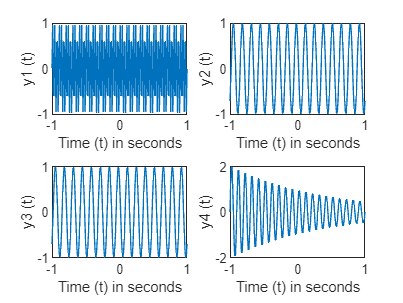

% Q1)
figure;
subplot(2,2,1);
t = -1:0.01:1;
y1 = sin(20*pi*a*t);
plot(t, y1)
xlabel('Time (t) in seconds')
ylabel('y1 (t)')


subplot(2,2,2);
t = -1:0.01:1;
y2 = cos(5*pi*a*t + (pi/4));
plot(t, y2)
xlabel('Time (t) in seconds')
ylabel('y2 (t)')


subplot(2,2,3);
y3 = exp(-2*a*t);
plot(t, y2)
xlabel('Time (t) in seconds')
ylabel('y3 (t)')

subplot(2,2,4);
y4 = exp(-0.25*a*t) .* sin(20*pi*t);
plot(t, y4)
xlabel('Time (t) in seconds')
ylabel('y4 (t)')

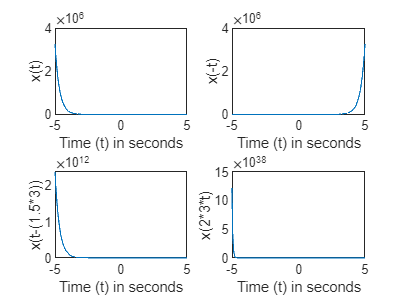

%Q2)
t = -5:0.01:5;
subplot(2,2,1);
x = inline('exp(-3*t)','t');
plot(t,x(t));
xlabel('Time (t) in seconds')
ylabel('x(t)')
subplot(2,2,2);
y1 = inline('x(-t)','x','t');
plot(t,y1(x,t));
xlabel('Time (t) in seconds')
ylabel('x(-t)')
subplot(2,2,3);
y2 = inline('x(t-(1.5*3))','x','t');
plot(t,y2(x,t));
xlabel('Time (t) in seconds')
ylabel('x(t-(1.5*3))')
subplot(2,2,4);
y3 = inline('x(2*3*t)','x','t');
plot(t,y3(x,t));
xlabel('Time (t) in seconds')
ylabel('x(2*3*t)')

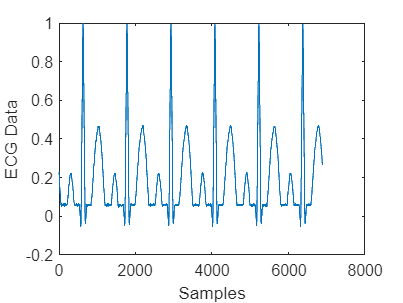

%Q3)

%1)
ECG_data = importdata('ECG_Data.txt');
figure;
plot(ECG_data);
xlabel('Samples')
ylabel('ECG Data')

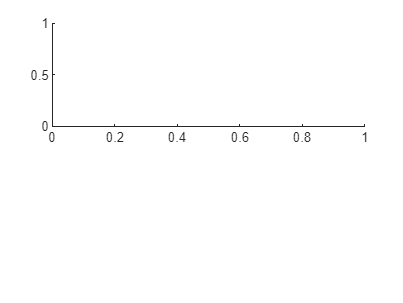

%2)
subplot(2,1,1);

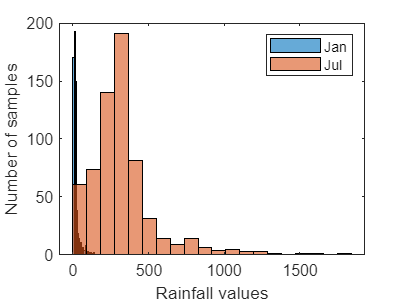

Jan = importdata('RainFallIndia_Jan.txt');
Jul = importdata('RainFallIndia_July.txt');
figure;
bins = 20;
h1 = histogram(Jan,bins);
hold on
h2 = histogram(Jul,bins);
legend();
xlabel('Rainfall values')
ylabel('Number of samples')


%3)
[y,Fs] = audioread('Track003.wav');
y

y =     0.1351
    0.1443
    0.1452
    0.1451
    0.1652
    0.1836
    0.1632
    0.1314
    0.1407
    0.1778


Fs

Fs = 44100

sound(y,Fs);

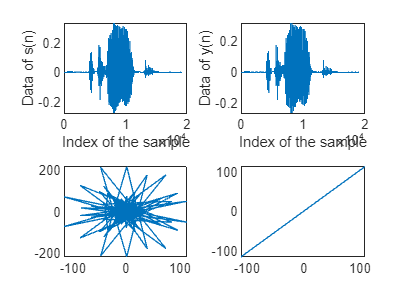

%Q4)
[s_n,Fs2] = audioread("speech.wav");
F = 250 * a;
y = s_n * cos(2*pi*F/Fs2);
subplot(2,2,1);
plot(s_n);
xlabel('Index of the sample');
ylabel('Data of s(n)');
subplot(2,2,2);
plot(y);
xlabel('Index of the sample');
ylabel('Data of y(n)');
s_fft = fft(s_n);
y_fft = fft(y);
subplot(2,2,3);
plot(s_fft);
subplot(2,2,4);
plot(y_fft,s_fft);

filename = 'speech.wav';  % Replace with the actual sampling frequency

% Read the speech signal
[s, Fs_s] = audioread(filename);

F=250 * 3 ;
y=s.*cos(2*pi*F/Fs_s);
% sound(y,Fs_s);
n=0:length(s)-1;
subplot(4,1,1)
plot(n,s)
subplot(4,1,2)
plot(n,y)


S=fft(s);
Y=fft(y);
subplot(4,1,3)
plot(S,Y)

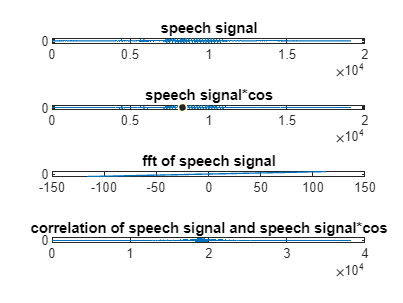

subplot(4,1,4)
corr=xcorr(s,y);
plot(corr)

subplot(4,1,1)
title("speech signal")
subplot(4,1,2)
title("speech signal*cos")
ax = gca;
chart = ax.Children(1);
datatip(chart,8321,-0.01403);
subplot(4,1,3)
title("fft of speech signal")
subplot(4,1,4)
title("correlation of speech signal and speech signal*cos")

%Q5)
t = [0:0.001:5];
y1 = sin(2*pi*200*a*t);
y2 = sin(2*pi*220*a*t);
y3 = [y1,y2];
sound(y3,10000)

%Q6)
s1 = sin(2*pi*240*t);
s2 = sin(2*pi*270*t);
s3 = sin(2*pi*300*t);
s4 = sin(2*pi*320*t);
s5 = sin(2*pi*360*t);
s6 = sin(2*pi*400*t);
s7 = sin(2*pi*450*t);
s8 = sin(2*pi*480*t);
s = [s1,s2,s3,s4,s5,s6,s7,s8];
sound(s,7000)
audiowrite("Doremi.wav",s,7000)

%Q7)
[track3,Fs] = audioread("Track003.wav");
conv3 = importdata("ConvFile3.txt");
convolved_data = conv(track3,conv3);
audiowrite("Convolved_track_3.wav",convolved_data,44100);

new_wav_data = audioread("Convolved_track_3.wav");
sound(new_wav_data,44100)
%Since the frequencies audible seem to be only those in the higher end in
%the convolved track, the guess would be that the given filter is a high
%pass filter.